# Monte Carlo of GoHorse Optimization - *fmincon(.)*

Default config

%close all;
clear;
clc;
set(0,'defaultfigurecolor',[1 1 1]);

Initialize variables and set the Monte Carlo configurations

MCruns = 100;

par = cell(MCruns,1);
J = cell(MCruns,1);
e_flag = cell(MCruns,1);
cruze = cell(MCruns,1);

## Generate the data or load pre-saved ones

Define the number of information data

WL = autoGen(14);
[dtd,dtn,A] = alertness_gen(2,WL,'random','not');
%load('monte_data.mat');

est_d = 7;

dte.y = dtd.y(1:est_d); dte.t = dtd.t(1:est_d);
dte.init = dtd.initial(1:est_d); dte.final = dtd.final(1:est_d); 
dte.valid.y = dtd.y(est_d+1:end); dte.valid.t = dtd.t(est_d+1:end);
dte.valid.init = dtd.initial(est_d+1:end); dte.valid.final = dtd.final(est_d+1:end);

A.valid.Ad = A.Ad(est_d+1:end); A.valid.td = A.td(est_d+1:end);
A.valid.An = A.An(est_d+1:end); A.valid.tn = A.tn(est_d+1:end);

Create  a variable for noise manipulation on simulation

y_c = dte.y;

## Optimization setup

options = optimoptions('fmincon','Algorithm','sqp','Display','off','MaxIter',50,...
    'UseParallel',true);
prop = .2;

## Introducing Constrains

lb = [.1, .1, .1, -2*pi, .1, .1, .1];
ub = [pi, inf, inf, 2*pi, inf, inf, inf];

## Real parameters

rPar(1) = pi/12; %omega
rPar(2) = 1/0.0353; %tau
rPar(3) = 2.52; %M
rPar(4) = -16.835*pi/12; %cPhase
rPar(5) = 2.4; %offset
rPar(6) = 14.3; %y_oo
rPar(7) = 2.6247; %tau_e

TexNames{1} = '$$\omega_n$$'; 
TexNames{2} = '$$\tau$$';
TexNames{3} = '$$M$$'; 
TexNames{4} = '$$\phi_{c}$$'; 
TexNames{5} = '$$A_{DC}$$'; 
TexNames{6} = '$$y_{\infty}$$';
TexNames{7} = '$$\tau_{e}$$';

## Initialize the Monte Carlo Simulations

for mc = 1 : MCruns
    
    rng('shuffle');
    
    noise_nat = 'colored';
    SNR = 40;
    to = cell2mat(dte.t);

    if strcmp(noise_nat,'white')
        e = idinput(length(cell2mat(y_c)),'rgs')*...
                                          std(cell2mat(y_c))*10^(-SNR/20);
        yo = cell2mat(y_c) + e;
    elseif strcmp(noise_nat,'colored')
        e = filter(1,[1 -.9],randn(length(cell2mat(y_c)),1));
        v = e*std(cell2mat(y_c))*10^(-SNR/20)/std(e);
        e = v;
        yo = cell2mat(y_c) + e;
    elseif strcmp(noise_nat,'noNoise')
        yo = cell2mat(y_c);
    end

    for w = 1 : length(y_c)
       ind = find((to>=dte.t{w}(1)).*(to<=dte.t{w}(end)));
       dte.y{w} = yo(ind);
    end
    
    cruze{mc} = prop.*rPar.*(rand(1,length(rPar))-.5);
    
    init = rPar + cruze{mc};
   
    [par{mc},J{mc},e_flag{mc}] = fmincon(@ghCost,init,[],[],[],[],lb,ub,[],options,dte);
    
    disp(['Monte Carlo run ',num2str(mc),...
                             ' Quadratic Error: ',num2str(J{mc})]);
end

## Monte Carlo figures

Plot the optimization output flags propotions and the cost function results 

labels = {'Maximum constrains violation','No feasible solution','Stopped by output funtion',...
    'Iterations exceeded','Conveged to selected options','Step Tolerance stopped',...
    'Cost function variation tolerance achieved', 'Step Tolerance to small',...
    'Derivative direction magnitude achieved'};
flags = cell2mat(e_flag)'+4;
e_flags = [count(num2str(flags),"1"), count(num2str(flags),"2"), count(num2str(flags),"3"),...
           count(num2str(flags),"4"), count(num2str(flags),"5"), count(num2str(flags),"6"),...
           count(num2str(flags),"7"), count(num2str(flags),"8"), count(num2str(flags),"9")];

figure(2); hold on;
subplot(2,1,1); 
histogram(cell2mat(J),20);
subplot(2,1,2); 
pie(e_flags,[0, 0, 0, 0, 1, 0, 0, 0, 0],labels); hold off;

Generate the visualization from for the cruze signal variations

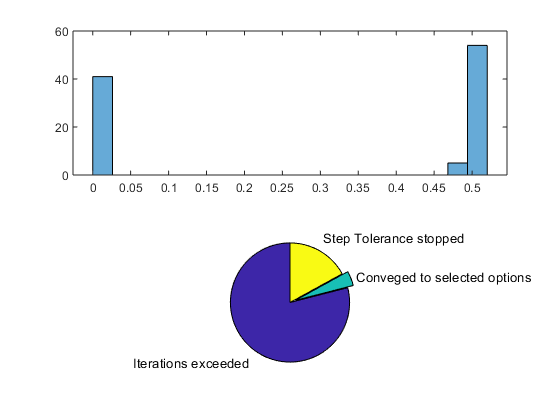

figure(5); hold on;

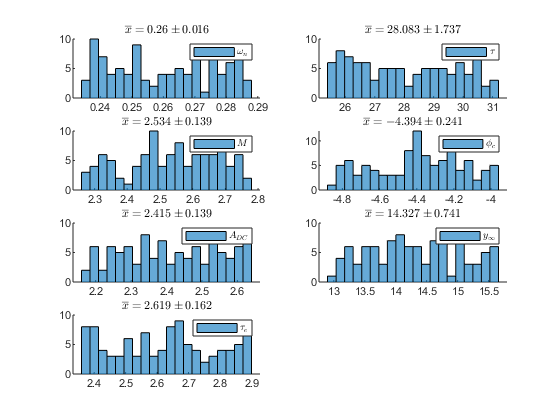

%title('Parameters initialization cruzing','Interpreter','latex');
aux = cell2mat(cruze);
for i = 1 : 7
   subplot(4,2,i); hold on;
   histogram(aux(:,i)+rPar(i),20); hold on;
   title(['$$\overline{x} =',num2str(round(mean(aux(:,i)+rPar(i)),3)),...
       '\pm',num2str(round(std(aux(:,i)+rPar(i)),3)),'$$'],...
       'Interpreter','latex');
   leg = TexNames{i};
   legend(leg,'Interpreter','latex'); hold off;
end

Plot the proportional error for each parameter at each run

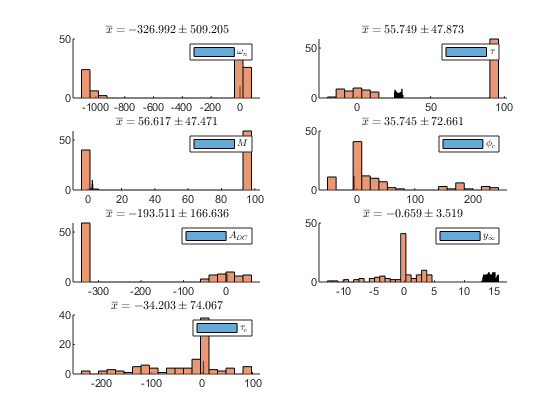

figure(12); hold on;
aux_i = cell2mat(par);
for i = 1 : 7
   subplot(4,2,i); hold on;
   e_prop = 100.*(rPar(i) - aux_i(:,i))/rPar(i); 
   histogram(e_prop,20); hold on;
   title(['$$\overline{x} =',num2str(round(mean(e_prop),3)),...
       '\pm',num2str(round(std(e_prop),3)),'$$'],'Interpreter','latex');
   leg = TexNames{i};
   legend(leg,'Interpreter','latex'); hold off; 
end